# Modifying Squishy Data Processing

Things we want to include:

- one matrix for all our data

- should combine with CaSO4_mixing file

- make this one big function file

Chopping off the outlier data

good_rows = 1:1300;
conductivity_list = conductivity_list(good_rows,:);
permeate_flowrate_list = permeate_flowrate_list(good_rows,:);
flowrate_list = flowrate_list(good_rows,:);
time_list = time_list(good_rows,:);

a/ Calculating salt rejection  = [1-(permeate conductivity)/(average conductivity on feed side of membrane)]

perm_conductivity = 0.5; % mS
salt_rej = (1-(perm_conductivity)/mean(conductivity_list))*100 % percentage

salt_rej = 87.7873

b/ Calculate the calcium sulfate concentration at the membrane at each timestep (from input initial concentration and instantaneous recovery and including concentration polarization.)

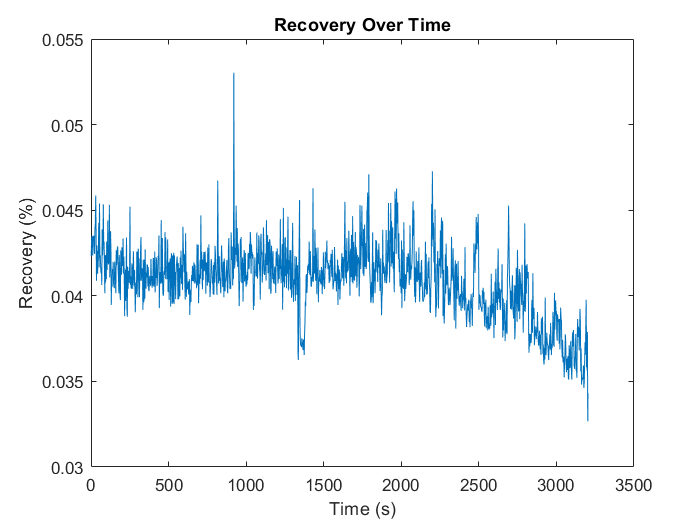

initial_conc = 450;    % intial concentration mol/L
mem_const = 0.99;  % membrane constant (K) 

recovery = (permeate_flowrate_list./flowrate_list);  %expressed in terms of a decimal
mem_CaSO4_conc = (1./(1-recovery)) .* initial_conc;          % membrane CaSO4 concentration
conc_polar = mem_const * exp(permeate_flowrate_list./mean(flowrate_list)); % concentration polarization

%plotting recovery
plot(time_list,recovery)
title('Recovery Over Time')
xlabel('Time (s)')
ylabel('Recovery (%)')

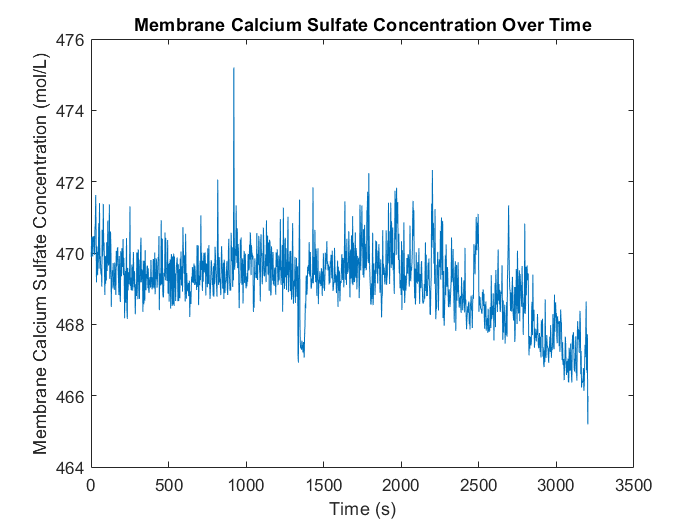


%plotting Membrane Calcium Sulfate Concentration
plot(time_list,mem_CaSO4_conc)
title('Membrane Calcium Sulfate Concentration Over Time')
xlabel('Time (s)')
ylabel('Membrane Calcium Sulfate Concentration (mol/L)')

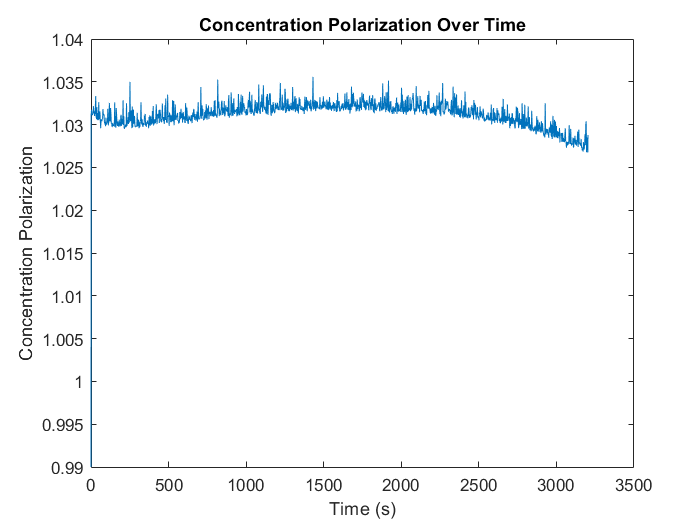


%plotting Concentration Polarization
plot(time_list,conc_polar)
title('Concentration Polarization Over Time')
xlabel('Time (s)')
ylabel('Concentration Polarization')


% title('')
% xlabel('')
% ylabel('')

c/ Calculate the saturation index of gypsum (a.k.a. calcium sulfate dihydrate) at the membrane at each timestep.

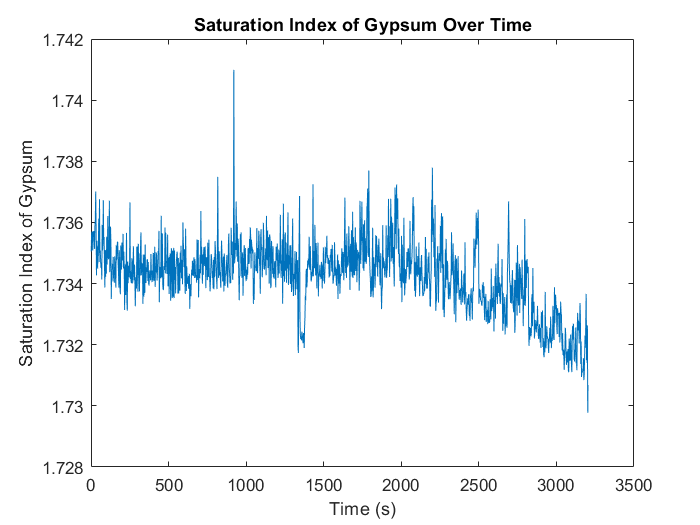

% equation in comments of doc
sat_index = 0.527 .* log(mem_CaSO4_conc) - 1.5073;

% plotting Saturation Gypsum over time
plot(time_list,sat_index)
title('Saturation Index of Gypsum Over Time')
xlabel('Time (s)')
ylabel('Saturation Index of Gypsum')

d/ Calculate the nucleation induction time of gypsum at each timestep.

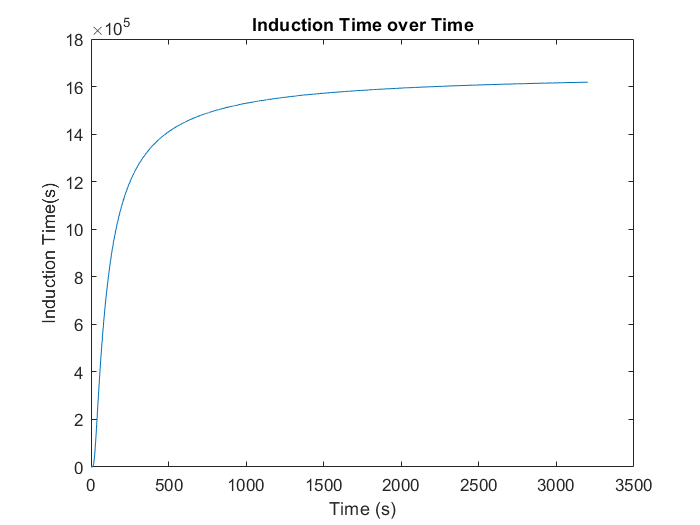

% ---------------------- hmmmmmmmmmmm
conc_over_time = mem_CaSO4_conc ./ time_list; % Membrance Concentration over Time (need to find out units)
ind_time = 1.66*(10^6).*(exp(-0.174*conc_over_time)); % Induction Time in seconds (s)

%plotting Induction Time over Time  hmmmmmmmmmm
plot(time_list,ind_time)
title('Induction Time over Time')
xlabel('Time (s)')
ylabel('Induction Time(s)')

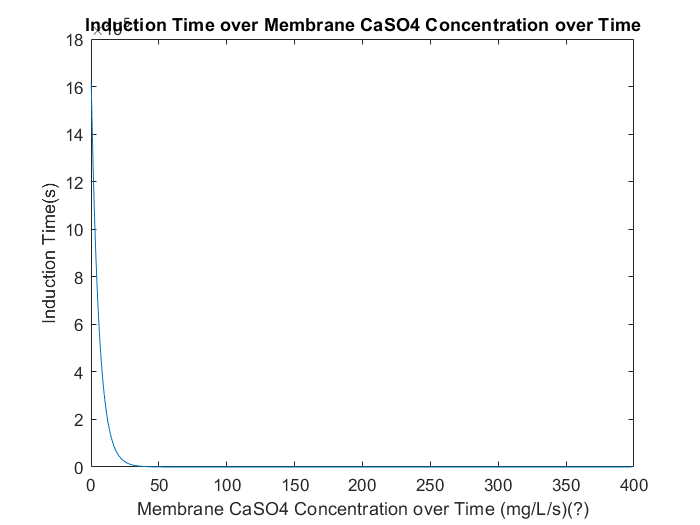


%plotting Induction Time over Membrane CaSO4 Concentration over Time
plot(conc_over_time,ind_time)
title('Induction Time over Membrane CaSO4 Concentration over Time')
xlabel('Membrane CaSO4 Concentration over Time (mg/L/s)(?)')
ylabel('Induction Time(s)')

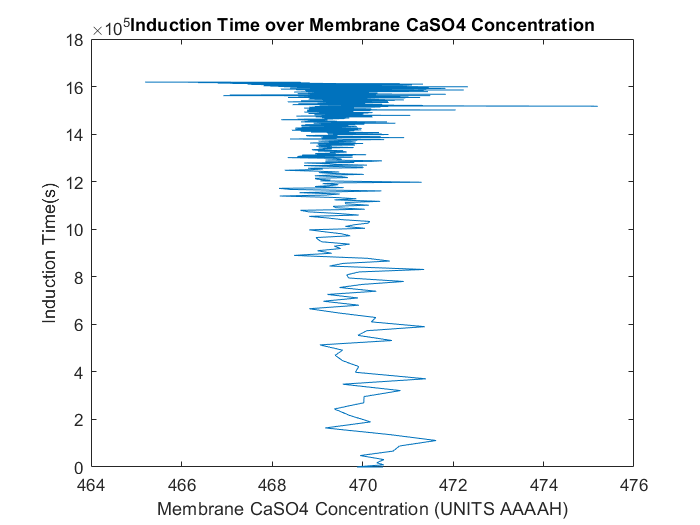


%plotting Induction Time over Membrance CaSO4
plot(mem_CaSO4_conc,ind_time)
title('Induction Time over Membrane CaSO4 Concentration')
xlabel('Membrane CaSO4 Concentration (UNITS AAAAH)')
ylabel('Induction Time(s)')

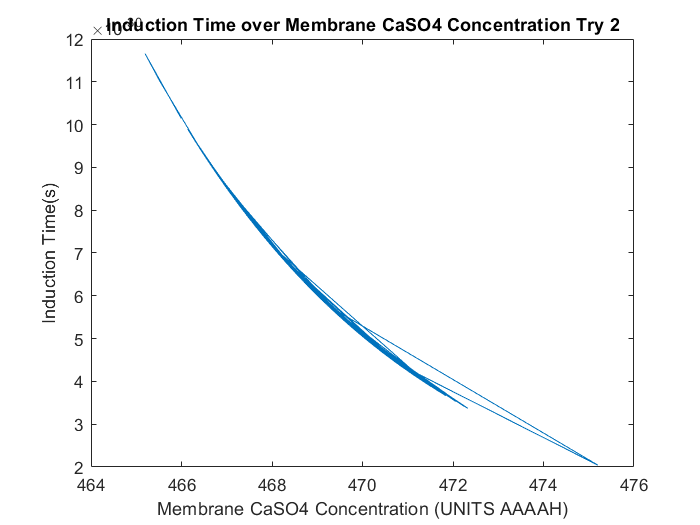


ind_time_2 = 1.66*(10^6).*(exp(-0.174*mem_CaSO4_conc)); % Induction Time in seconds (s)
plot(mem_CaSO4_conc,ind_time_2)
title('Induction Time over Membrane CaSO4 Concentration Try 2')
xlabel('Membrane CaSO4 Concentration (UNITS AAAAH)')
ylabel('Induction Time(s)')

e/ Integrate the induction rate (i.e., the inverse of induction time) over all timesteps in each batch cycle to determine the nucleation probability per cycle

% ----------------- hmmmmmmmmm
syms ind_time C_t
f(ind_time,C_t) = 1./(ind_time.*C_t)

$$f(ind\_time, C\_t) = \frac{1}{C_{t}\,{\mathrm{ind}}_{\mathrm{time}}}$$

fint = int(f,ind_time,C_t)

$$fint(C\_t) = \left\{ \begin{array}{cl} \frac{\int_{{\mathrm{ind}}_{\mathrm{time}}}^{C_{t}}\frac{1}{{\mathrm{ind}}_{\mathrm{time}}}\mathrm{d}{\mathrm{ind}}_{\mathrm{time}}}{C_{t}} & \text{ if }0\leq C_{t}\wedge {\mathrm{ind}}_{\mathrm{time}}\leq 0\\ \frac{\log\left(C_{t}\right)-\log\left({\mathrm{ind}}_{\mathrm{time}}\right)}{C_{t}} & \text{ if }C_{t}<0\vee 0<{\mathrm{ind}}_{\mathrm{time}} \end{array}\right.$$

%nucl_prob = int(1./(ind_time*C_t),time_list,0,500) 
plot(ind_time, C_t)

Error using plot
Data must be numeric, datetime, duration or an array convertible to double.